Work flow for cell suspension

1) Load pellet or cells and get mz (x axiz) - 3-4 cm, 0.2 second per scan, 40 scans

2) No peak picking, 

3) Try to recalibrate with the most m/z values giving the lowest ppm, try get below 10 ppm

4) check reclibration with excel file "check recalibration"

  255.2324 

  788.5441 

  802.5604 

  885.5499 

5) Then load all the other samples 

MS_Workflow_1_PreProcessing

%% OUTLINE
% 1. Import spectra
% 2. Gate scans
% 3. Peak pick
% 4.a. Align (create global mz)
% 4.b. Align (apply global_mz with interpSpec)? do we need dum_specs?
% 5. Recalibrate
% 6. Normalise 
% 7. Output & Name 
% 8. Mean Figures 

%PATHWAY
%make sure the path is set to "\\icnas4.cc.ic.ac.uk\cm19\MATLAB"
% Pathway 
cd C:\Documents\2021\2021_Oct\mstb_toolbox\mstb-main
MS_path = 'C:\Documents\2021\2021_Oct'; % complete path to mstb-main
addpath(genpath(MS_path))
addpath(genpath(pwd));

%% 1. Import Spectra

%Opens the raw file (SamplingRate(how many m/z values incluing 0s)=numP2 and CellOfM/Z&Intensity=Specs2)
[specs2,numP2] = desiReadRaw('F:\2023\March 2023\solvents March 2023\2023_03_07_CM_IPA5_MWPEL05_5KV_10CM_002ST.raw',0);

Elapsed time is 0.077606 seconds.



%No. of scans for cells
%Cell_Flow_Rate (ul/min)
%Cell_Concentration (cells/mL)
%Scan_Rate (second/scan)
%no. of cells desired is 1

Cell_Flow_Rate=0.5;
Cell_Concentration=1000000;
Scan_Rate=0.2;
Desired_Cell_No=2;
No_of_scans = 1/(Scan_Rate*Cell_Flow_Rate*(1/60)*Cell_Concentration*(1/1000)*(1/Desired_Cell_No))

No_of_scans =           1.2

Info_List = [Cell_Flow_Rate,Cell_Concentration,Scan_Rate,Desired_Cell_No,No_of_scans]'

Info_List =           0.5
        1e+06
          0.2
            2
          1.2



%Total Ion Chount (ans=TotalIonCount,scanOrTime)
TIC(specs2);

Elapsed time is 0.275191 seconds.


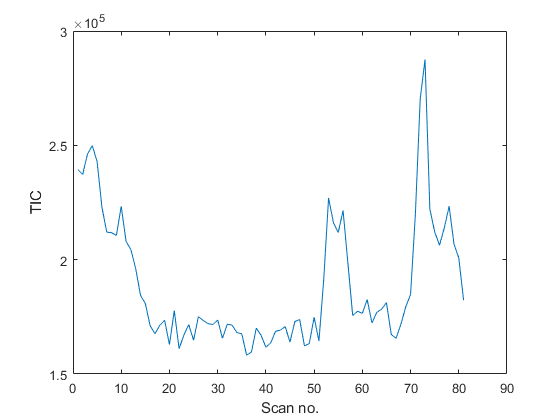

plot(ans);
xlabel('Scan no.');
ylabel('TIC');

%xlim([0 500])

%Total Ion Chount (ans=TotalIonCount,scanOrTime)
TIC(specs2);
plot(ans);
xlabel('Scan no.');
ylabel('TIC');
%xlim([0 500])


%% 2. Gate Scans
%Only keep wanted scans (choose best 200 scans! no dips!)
% X = First scan no.
% Y = Last scan no.
x = 200;
y = 400;
numP2_gated=numP2(x:y);
specs2_gated=specs2(x:y);

%% 3. Preview Plot Raw
% Align Raw
spectral_lens = [];
for i = 1:length(specs2_gated)
    spectral_lens(i) = length(specs2_gated{i});
end
[~,ind_max] = max(spectral_lens);
raw_mz = specs2_gated{ind_max}; raw_mz = double(raw_mz(1,:));
%Apply Align Raw
specs_dum = interpSpec(specs2_gated,raw_mz,length(specs2_gated));

Elapsed time is 0.457682 seconds.


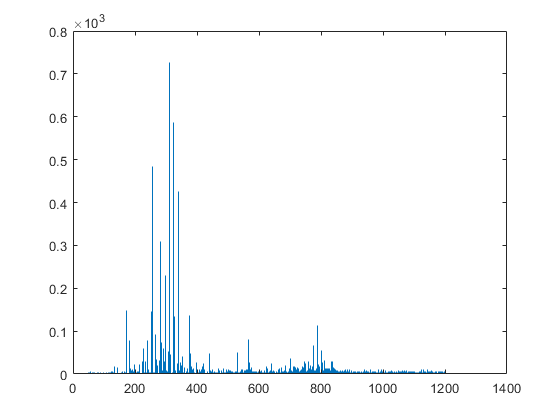

% specs_dum = interpSpec(specs2,new_mz,length(numP2_gated));
%set all nan to 0
specs_dum(isnan(specs_dum))=0;
specs_dum_raw=specs_dum;
%plot
% figure,plot(new_mz,mean(specs_dum))
figure,stem(raw_mz,mean(specs_dum_raw),'Marker','none')
ax = gca;
ax.YAxis.Exponent = 3;

%xlim([400 1200])


%% 3. Peak pick (or denoise with BA_cwtpp)
%Why? because no universal threshold , 
%when doing 10% of highest intensity peak, but this changes

%1.peak detection using wavelit transform, 
%level 8 only picks peaks that are gaussian (not noise) and high intenisity
%highest level first
%also centroids peaks (not gaussian anymore)
%below 3 is removed
%threshold on 'peak prominance' not peak intensity
%2.it also removes instrumnetal noise or spectral background)

    
%For no Pick Picking
pd=specs2_gated;

%pd=cwtpp(specs2_gated,X);
% for X, 5% threshold is 5
%for new cwtpp location \\icnas4.cc.ic.ac.uk\cm19\GitHub\oycxms
x = 0.001
%addpath(genpath('C:\Documents\2022\Feb 2022\FCMS_WORK_FLOW'))
addpath(genpath('\\icnas4.cc.ic.ac.uk\cm19\GitHub\oycxms'))
pd=cwtpp(specs2_gated,(x*10));

%use 'stem' to plot and remove 

    %SKIP TO 4b (2nd sample)
    %use 'stem' to plot and remove 
    %% !4.a Align (create global_mz)
    %NOT for second sample
    %Align The Spectra to max number of m/z channels (because peaks are
    %gaussian?) !Align to 1 axis, every scan within the cell line is going to
    %have the same axis!
    %look at TIC and decide length of x (number of scans)
    %work out median sampling rate
    %interpSpec( spec,new_mz,size )
    % size = number of scans
    spectral_lens = [];
    for i = 1:length(pd)
        spectral_lens(i) = length(pd{i});
    end
    [~,ind_max] = max(spectral_lens);
    global_mz = pd{ind_max}; global_mz = double(global_mz(1,:));
    %new_mz = pd{find(numP2_gated==median(numP2_gated)),1};
    %new_mz is the spectra we align to median (only do for mixed sample)
    
    %if you loose new_mz
    %global_mz=MWpel_NEWMZ
    
%% 4.b. Align (apply global_mz with interpSpec)
specs_dum = interpSpec(pd,global_mz,length(pd));

Elapsed time is 0.301429 seconds.


% specs_dum = interpSpec(specs2,new_mz,length(numP2_gated));
%set all nan to 0
specs_dum(isnan(specs_dum))=0;
%plot
% figure,plot(new_mz,mean(specs_dum))
figure,stem(global_mz,mean(specs_dum),'Marker','none')
ax = gca;
ax.YAxis.Exponent = 3;

the average ppm before correction is 9.5532
the average ppm after correction is 3.54
the average ppm before correction is 3.54
the average ppm after correction is 4.297


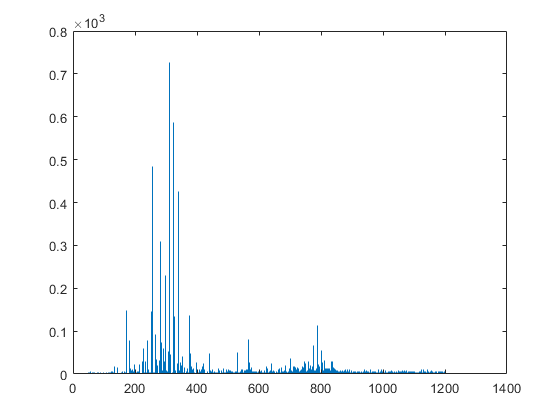


%% 5a. Recalibrate 
% Mass correct to:
% 255.2324 m/z which is Palmitic Acid [M-H]- also in blank
% 273.0392 m/z which is Deoxy sedoheptulose phosphate [M-H]-  
% 283.2649 m/z which is Stearic Acid [M-H]- also in blank
% ADDED 628.0562 m/z which is UDP-GalNAc [M+Na-2H]-
% 766.5392 m/z which is PE(38:4) [M-H]- 
% 774.5352 m/z which is PS (35:1) [M-H]-
% 789.5498 m/z which is PA(43:6) [M-H]-
% ADDED 794.5472 m/z which is PE (37:1) [M+Cl]-
% 885.5499 m/z, which is PI (38:4) [M-H]-

addpath(genpath('C:\Documents\2022\Feb 2022\FCMS_WORK_FLOW'))

     threshold = 500;%in ppm

    references = [255.2324, 273.0381, 283.2643, 628.0562, 766.5392, 774.5291, 789.5440, 794.5472, 885.5499];

[new_mz,~] = MSrecal(global_mz,references, threshold);

figure,stem(new_mz,mean(specs_dum),'Marker','none')
ax = gca;
ax.YAxis.Exponent = 3;


%% 5b. 2nd calibration (adjust until below 10 ppm)
% Mass correct to:
% 255.2324 m/z which is Palmitic Acid [M-H]- also in blank
% 273.0392 m/z which is Deoxy sedoheptulose phosphate [M-H]-  
% 283.2649 m/z which is Stearic Acid [M-H]- also in blank
% ADDED 628.0562 m/z which is UDP-GalNAc [M+Na-2H]-
% R- 766.5392 m/z which is PE(38:4) [M-H]- 
% R- 774.5352 m/z which is PS (35:1) [M-H]-
% 789.5498 m/z which is PA(43:6) [M-H]-
% ADDED 794.5472 m/z which is PE (37:1) [M+Cl]-
% 885.5499 m/z, which is PI (38:4) [M-H]-

addpath(genpath('C:\Documents\2022\Feb 2022\FCMS_WORK_FLOW'))

     threshold = 500;%in ppm

     references = [255.2324, 273.0381, 283.2643, 628.0562, 789.5440, 794.5472, 885.5499]; %Removed 766.5392 and 774.5291

[new_mz,ppms] = MSrecal(global_mz,references, threshold);

the average ppm before correction is 11.7858
the average ppm after correction is 2.0859
the average ppm before correction is 2.0859
the average ppm after correction is 5.1141



figure,stem(new_mz,mean(specs_dum),'Marker','none')
ax = gca;
ax.YAxis.Exponent = 3;


%% 5c. 3rd Recalibrate
% Mass correct to:
% 255.2324 m/z which is Palmitic Acid [M-H]- also in blank
% 273.0392 m/z which is Deoxy sedoheptulose phosphate [M-H]-  
% 283.2649 m/z which is Stearic Acid [M-H]- also in blank
% ADDED 628.0562 m/z which is UDP-GalNAc [M+Na-2H]-
% 766.5392 m/z which is PE(38:4) [M-H]- 
% 774.5352 m/z which is PS (35:1) [M-H]-
% 789.5498 m/z which is PA(43:6) [M-H]-
% ADDED 794.5472 m/z which is PE (37:1) [M+Cl]-
% 885.5499 m/z, which is PI (38:4) [M-H]-

addpath(genpath('C:\Documents\2022\Feb 2022\FCMS_WORK_FLOW'))

     threshold = 500;%in ppm

     references = [255.2324];%273.0381, 283.2643

[new_mz,ppms] = MSrecal(global_mz,references, threshold);

the average ppm before correction is 1.11
the average ppm after correction is 19619.4841



figure,stem(new_mz,mean(specs_dum),'Marker','none')
ax = gca;
ax.YAxis.Exponent = 3;

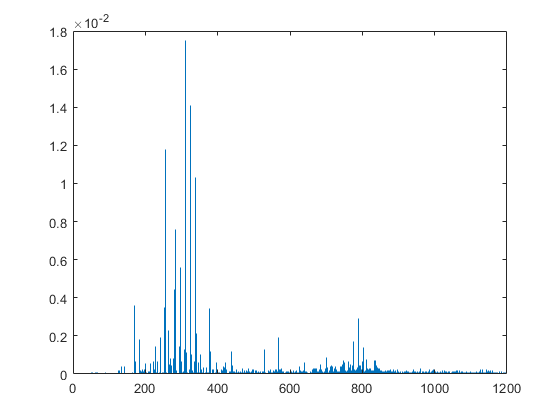



%% 5d. 4th Recalibrate (more than mz values than 3rd, BETTER)
%% 5g. 7th Recalibrate 
% Mass correct to:
% 255.2324 m/z which is Palmitic Acid [M-H]- also in blank
% 273.0392 m/z which is Deoxy sedoheptulose phosphate [M-H]-  
% 283.2649 m/z which is Stearic Acid [M-H]- also in blank
% ADDED 628.0562 m/z which is UDP-GalNAc [M+Na-2H]-
% 766.5392 m/z which is PE(38:4) [M-H]- 
% 774.5352 m/z which is PS (35:1) [M-H]-
% 789.5498 m/z which is PA(43:6) [M-H]-
% ADDED 794.5472 m/z which is PE (37:1) [M+Cl]-
% 885.5499 m/z, which is PI (38:4) [M-H]-

addpath(genpath('C:\Documents\2022\Feb 2022\FCMS_WORK_FLOW'))

     threshold = 500;%in ppm

    references = [255.2324, 283.2643, 774.5291, 885.5499];
    

[new_mz,~] = MSrecal(global_mz,references, threshold);

figure,stem(new_mz,mean(specs_dum),'Marker','none')
ax = gca;
ax.YAxis.Exponent = 3;




%% 6. Normalise
TIC_Norm_path = 'C:\Documents\2022\Feb 2022\FCMS_WORK_FLOW'; % complete path to mcr_toolbox2
addpath(genpath(TIC_Norm_path))
%run
specs_input = specs_dum;
norm_specs= BB_TIC_norm(specs_input);
%remove NAN
norm_specs(isnan(norm_specs))=0;

figure,stem(new_mz,mean(norm_specs),'Marker','none')
ax = gca;
ax.YAxis.Exponent = -2;
xlim([0 1200]) 



    %% 7.a. OUTPUT (for spectral unmixing)
    %the x axis is 'new_mz'
    %the y axis' are 'norm_specs'
    %norm_specs: y is scans x is m/z channels 
    %Name
    A_SPECS = norm_specs;
    A_NEWMZ = new_mz;

    

MS_WorkFlow_3b_Solvent_Subtraction

C:\Documents\2022\Feb 2022\FCMS_WORK_FLOW\MS_WorkFlow_3b_Solvent_Subtraction.m

      
%% Remove Solvent Peaks

% Sample=cells_5050_50to250_01PeakPick;
%A=Blank_Mean(:,2);

%Input:

    new_mz= A_Pel_W_NEWMZ_1stcal;

    Sample = mean(A_Pel_SPECS_1stcal)'; %Pellet
    Blank = mean( A_Sup_SPECS)'; %Supernatant
    Actual_Solvent_Blank = mean(A_SPECS)'; %Solvent Blank

new_mz =        49.831        55.56       55.562       55.563       55.565        57.03       57.032       57.033       57.035       62.872       62.874       62.876       62.877       63.756       63.758       63.759       63.761       63.905       63.907       63.908        63.91       63.941       63.942       63.944       63.946       70.996       70.998           71       71.001       94.451       94.453       94.455       94.457       109.81       109.82       109.82       109.82        120.6        120.6        120.6        120.6       140.12       140.13       140.13       140.13       140.88       140.88       140.88       140.88       142.94


    Cells= mean(A_Cell_SPECS_1stcal)'; %Cell Suspension

%Run:

Sample= rescale(Sample,0,1);
Blank= rescale(Blank,0,1);
Actual_Solvent_Blank= rescale( Actual_Solvent_Blank,0,1);
Cells= rescale(Cells,0,1);

%Subtract Supernatant
A =  Blank;
%Normalise blank between 0 and 1
A = rescale(A, 0, 1);
%the x axis is 'new_mz'
%the y axis is 'mean(norm_specs)'
%plot
stem(new_mz,A,'Marker','none','Color','k')
xlabel('{\it m/z}');
ylabel('Relative Intensity');
title ('Normalised July 2021' )
%subtitle('(Peak Picked (0.1%), Aligned, Recalibrated & Normalised)')
%ax = gca;
%ax.YAxis.Exponent = -2;
xlim([0 1200])
%ylim([0 1])
%When blank is above 5% threshold intensity = 0
A(A>=0.05) = 0; 
%When blank is below 5% threshold intensity = 1
A(A>0) = 1; 
%sample X blank mask = solvent subtracted sample
%Sup_Subtracted = Sample.*A;
Subtracted = Sample.*A;

    %Subtract Solvent
    Sample=Sup_Subtracted
    A =   Actual_Solvent_Blank;
    %Normalise blank between 0 and 1
    A = rescale(A, 0, 1);
    %the x axis is 'new_mz'
    %the y axis is 'mean(norm_specs)'
    %plot
    stem(new_mz,A,'Marker','none','Color','k')
    xlabel('{\it m/z}');
    ylabel('Relative Intensity');
    title ('Normalised July 2021' )
    %subtitle('(Peak Picked (0.1%), Aligned, Recalibrated & Normalised)')
    %ax = gca;
    %ax.YAxis.Exponent = -2;
    xlim([0 1200])
    %ylim([0 1])
    %When blank is above 5% threshold intensity = 0
    A(A>=0.1) = 0; 
    %When blank is below 5% threshold intensity = 1
    A(A>0) = 1; 
    %sample X blank mask = solvent subtracted sample
    Subtracted = Sample.*A;


%What is this??
%a = A;
%b = Sample;
%x = repmat(a,1,size(b,2));
%x.*b % or dot(x,b)

ans =             0
            0
   6.2751e-05
   4.9354e-05
            0
            0
            0
            0
            0
            0


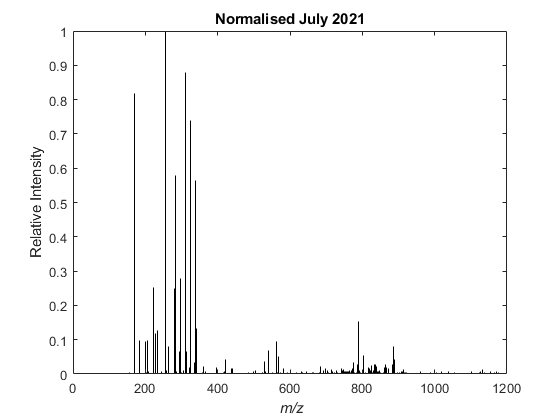



%PLOT
tiledlayout(2,2)

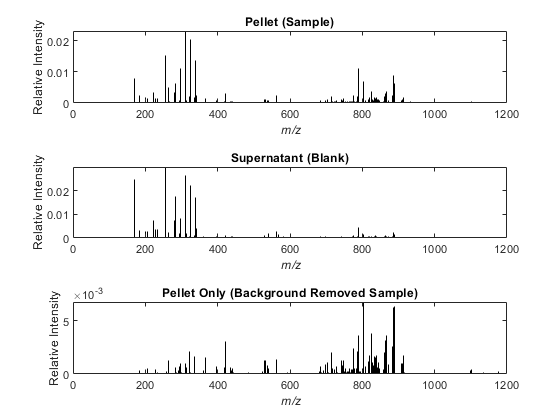


nexttile
%plot Sample
stem(new_mz,Actual_Solvent_Blank,'Marker','none','Color','k')
xlabel('{\it m/z}');
ylabel('Relative Intensity');
title ('Solvent Blank' )
ax = gca;
%ax.YAxis.Exponent = -2;
xlim([0 1200])
ylim([0 1])

nexttile
%plot Sample
stem(new_mz,Cells,'Marker','none','Color','k')
xlabel('{\it m/z}');
ylabel('Relative Intensity');
title ('Cell Suspension' )
ax = gca;
%ax.YAxis.Exponent = -2;
xlim([0 1200])
ylim([0 1])

nexttile
%plot Sample
stem(new_mz,Sample,'Marker','none','Color','k')
xlabel('{\it m/z}');
ylabel('Relative Intensity');
title ('Pellet' )
ax = gca;
%ax.YAxis.Exponent = -2;
xlim([0 1200])
ylim([0 1])

nexttile
%plot blank
stem(new_mz,Blank,'Marker','none','Color','k')
xlabel('{\it m/z}');
ylabel('Relative Intensity');
title ('Supernatant' )
ax = gca;
%ax.YAxis.Exponent = -2;
xlim([0 1200])
ylim([0 1])

tiledlayout(2,2)

nexttile
%plot subtracted
stem(new_mz,Subtracted,'Marker','none','Color','k')
xlabel('{\it m/z}');
ylabel('Relative Intensity');
title ('Pellet Only' )
subtitle('Minus Supernatant')
ax = gca;
%ax.YAxis.Exponent = -2;
xlim([0 1200])

ylim([0 1])
    
Subtracted_Pellet=Subtracted;

%now list all the molecules 
%then identify




## Molecules in pellet only 



%% 7.b. OUTPUT of MEAN (for cell library)

    %DELETE DATA
    DATA=[];
    %the x axis is 'new_mz'
    %the y axis is 'mean(norm_specs)'
    DATA(:,1)= A_Pel_W_NEWMZ_1stcal;
    DATA(:,2)= Subtracted_Pellet;

%Name %for control go to E now
%A549=DATA;
%MWpel_Mean=DATA;
intensity_norm = (DATA(:,2) - min(DATA(:,2))) / ( max(DATA(:,2)) - min(DATA(:,2)) );
%% Threshold Peaks Loop with haoyu
% i is changing!, loops know that i isnt actually the same every time.
threshold = [0.05, 0.1, 0.2];
X = [];
 for i = 1:3 %i is the size of the data (number of scans)
    % a. 5% Threshold
    % i.Remove bottom 5%
    dummy = intensity_norm;
    dummy( dummy <= threshold(i)) = 0;
    % ii. Optional Check 5% Plot 
    %figure,stem(DATA(:,1),intensity_norm_5,'Marker','none')
    %iii. Make Mask
    dummy_mask = dummy;
    dummy_mask( dummy_mask  >= threshold(i) ) = 1;
    %iv. Optional Check Mask
    %plot(DATA(:,1),intensity_norm_5_mask)
    %v. Apply Mask
    X(:,i) = DATA(:,1).*dummy_mask;
 end    
%vi. Table
X5=X(:,1);
X5=X5(X5 >0); %gives you all the values greater than zero            
X10=X(:,2);
X10=X10(X10 >0); %gives you all the values greater than zero  
X20=X(:,3);
X20=X20(X20 >0); %gives you all the values greater than zero

Subtracted_Pellet_Thresholds=X;
%MW_Cells_Thresholds=X;


%% 4. Array of Threshold Peaks

%ii.Peaks found in both samples (X5 and X10) - X5 perspective
 [val,pos]=intersect(X5,X10);
%"pos" is the position in X5 that is in X10 the blank
%Present in 5% and 10%
%mask for peaks found in both samples 
X5_mask=X5;
X5_mask(:,1)=0;
X5_mask(pos,1)=1;
%mask*peaks
Top5_and_Top10 =  X5_mask.*X5;

%ii.Peaks found in both samples (X5 and X20) - X5 perspective
 [val,pos]=intersect(X5,X20);
%"pos" is the position in X5 that is in X10 the blank
%Present in 5% and 10%
%mask for peaks found in both samples 
X5_mask=X5;
X5_mask(:,1)=0;
X5_mask(pos,1)=1;
%mask*peaks
Top5_and_Top20 =  X5_mask.*X5;

%MUST DELETE 'Table_5_10_20' first
Table_5_10_20=[];
%Array together
Table_5_10_20(:,1) = X5;
Table_5_10_20(:,2) = Top5_and_Top10;
Table_5_10_20(:,3) = Top5_and_Top20;

%Name 
Table_5_10_20_A_Pel_Only = Table_5_10_20;




## MS_WorkFlow_8_Lipidmaps

## C:\Documents\2022\Feb 2022\FCMS_WORK_FLOW\MS_WorkFlow_8_Lipidmaps.m


%%
%Go to lipid maps, copy and paste 5%, 10% then 20% threshold peaks and select for M-H and
%M+Cl [M+HCOO]- [M+OAc]- ions only m/z tolerance 0.01 m/z
%(https://www.lipidmaps.org/tools/ms/lm_bulk_search.php)
% https://www.lipidmaps.org/tools/ms/ 
% click General MS precursor ion search on multiple lipid classes
%Copy to excel and get length (no. of peaks)
c=cell(100);
%copy lipids maps and paste as excel data into 'c' (not titles!)
Names = c(:,4);
Tally = groupsummary(table(Names),"Names",'sum');
TallySort = sortrows(Tally,[2],{'descend'}); %These are ions that have been seen twice
%if too many delete all except FA's and P's

%%
%find(strcmp('FA(16:1(Ke,cyclo))',c));
%Index = find(contains(c(:,4),'FA(16:2(Ep))'));

%exact_match_mask = strcmp(c, 'FA(16:1(Ke,cyclo))''FA(16:2(Ke))');
%exact_match_locations = find(exact_match_mask);

%idx = find(strcmp([Names], 'FA(16:1(Ke,cyclo))')) % single line engine
%idx = find(strcmp([Names], 'FA(16:2(Ke))')) % single line engine

%%
%idx = find(strcmp([Names], TallySort.Names(1,1))) % to check
%exact_match_mask = strcmp(c, TallySort.Names(1,1));
mask_1 = strcmp(c, TallySort.Names(1,1));
mask_2 = strcmp(c, TallySort.Names(2,1));
mask_3 = strcmp(c, TallySort.Names(3,1));
mask_4 = strcmp(c, TallySort.Names(4,1));
mask_5 = strcmp(c, TallySort.Names(5,1));
mask_6 = strcmp(c, TallySort.Names(6,1));
mask_7 = strcmp(c, TallySort.Names(7,1));
mask_8 = strcmp(c, TallySort.Names(8,1));
mask_9 = strcmp(c, TallySort.Names(9,1));
mask_10 = strcmp(c, TallySort.Names(10,1));
mask_11 = strcmp(c, TallySort.Names(11,1));
mask_12 = strcmp(c, TallySort.Names(12,1));
mask_13 = strcmp(c, TallySort.Names(13,1));
mask_14 = strcmp(c, TallySort.Names(14,1));
mask_15 = strcmp(c, TallySort.Names(15,1));
mask_16 = strcmp(c, TallySort.Names(16,1));
mask_17 = strcmp(c, TallySort.Names(17,1));
mask_18 = strcmp(c, TallySort.Names(18,1));
mask_19 = strcmp(c, TallySort.Names(19,1));
mask_20 = strcmp(c, TallySort.Names(20,1));%Check TallySort and choose no of masks
Total_mask = mask_1 + mask_2 + mask_3 + mask_4 + mask_5 + mask_6 + mask_7 + mask_8 + mask_9 + mask_10 + mask_11 + mask_12 + mask_13 + mask_14 + mask_15 + mask_16 + mask_17 + mask_18 + mask_19 + mask_20
New_mask = Total_mask(:,4);

Peaks = cell2mat(c(:,1));
Peaks(:,2) = cell2mat(c(:,2));
Peaks_Masked = Peaks.*New_mask;

%find the indices of 
%Index = find(New_mask,1);
[row,col,v] = find(New_mask)
no=row'
c2=c(no(1,1),:);
c2(2,:)=c(no(1,2),:);
c2(3,:)=c(no(1,3),:);
c2(4,:)=c(no(1,4),:);
c2(5,:)=c(no(1,5),:);
c2(6,:)=c(no(1,6),:);
c2(7,:)=c(no(1,7),:);
c2(8,:)=c(no(1,8),:);
c2(9,:)=c(no(1,9),:);
c2(10,:)=c(no(1,10),:);
c2(11,:)=c(no(1,11),:);
c2(12,:)=c(no(1,12),:);
c2(13,:)=c(no(1,13),:);
c2(14,:)=c(no(1,14),:);
c2(15,:)=c(no(1,15),:);
c2(16,:)=c(no(1,16),:);
c2(17,:)=c(no(1,17),:);
c2(18,:)=c(no(1,18),:);
c2(19,:)=c(no(1,19),:);
c2(20,:)=c(no(1,20),:);
c2(21,:)=c(no(1,21),:);
c2(22,:)=c(no(1,22),:);
c2(23,:)=c(no(1,23),:);
c2(24,:)=c(no(1,24),:);
c2(25,:)=c(no(1,25),:);
c2(26,:)=c(no(1,26),:);
c2(27,:)=c(no(1,27),:);
c2(28,:)=c(no(1,28),:);
c2(29,:)=c(no(1,29),:);
c2(30,:)=c(no(1,30),:);

%opem c2
%now right click on the names column "sort by selected columns"  
%look where the adducts change to see if they are the same molecule

%%
% add to script cannot count same adducts
%to do, write a script that finds [M-H] and another adduct

%MAKE 2 tables a) [M-H] adducts b) [M+Cl] adducts
% look for names that are in both







## Other ?




%% 2 Samples

%% Peaks in Multiple Data Sets
%Import Data
Sample_1 = MW_Cells_Thresholds;
Sample_2 = MW_Subtracted_Pellet_Thresholds;

% 1 & 2 (10%)
%SAMPLE 1 PERSPECTIVE
%Shared peaks between sample and blank below a ppm error threshold 
addpath(genpath('C:\Documents\2022\Feb 2022\FCMS_WORK_FLOW'))
D1 = Sample_1(:,1); %Peaks above 10% threshold is column 1
D2 = Sample_2(:,1); %Peaks above 10% threshold is column 1
[D1_D2,ppms] = shared_mz(D1,D2);
%Sample Name
S1_S2=D1_D2;

%SAMPLE 2 PERSPECTIVE
%Shared peaks between sample and blank below a ppm error threshold 
[D2_D1,ppms] = shared_mz(D2,D1);
%Sample Name
S2_S1=D2_D1;
D1_D2_Av=[]
for i=1:length(D1_D2)
D1_D2_Av(i)=(D1_D2(i)+D2_D1(i))/2;
end
%Both_1_2=D1_D2_Av'
%% Name
BOTH_10_MW_Cells_Pellet_Av=D1_D2_Av';



    
    
    
    
%% Solvent Subtraction
%Import Data
%Sample = MDA_5_10_20;
%Blank = BLANK_MDA_5_10_20;
Sample = mean(MWpel_SPECS)';
Blank =  mean(MWsup_pmz_SPECS)';

plot(Sample)
plot(Blank)

%Shared peaks between sample and blank below a ppm error threshold 
addpath(genpath('C:\Documents\2022\Feb 2022\FCMS_WORK_FLOW'))
D1 = Sample(:,1); %Peaks above 5% threshold is column 1
D2 = Blank(:,1); %Peaks above 5% threshold is column 1
[D1_D2,ppms] = shared_mz(D1,D2);
%Name
D1_B1=D1_D2;
%find position of peaks in blank
[val,pos]=intersect(D1,D1_B1);

%Remove peaks in blank
%"pos" is the position in sample that is in the blank
%Present in 5% and 10%
%mask for peaks found in both samples 
mask=D1;
mask(:,1)=1;
mask(pos,1)=0;
%mask*peaks
Sample_Subtracted = mask.*Sample;

%add blank to 4th column
maskB=D1;
maskB(:,1)=0;
maskB(pos,1)=1;
Blank_List = D1.*maskB;
Sample_Subtracted(:,4) = Blank_List;

stem(MWpel_NEWMZ,Sample_Subtracted(:,1),'Marker','none','Color','k')
xlabel('{\it m/z}');
ylabel('Relative Intensity');
title ('Background Removed Sample' )
%subtitle('(Peak Picked (0.1%), Aligned, Recalibrated & Normalised)')
ax = gca;
%ax.YAxis.Exponent = -2;
xlim([0 1200])
%ylim([0 1])


%% Output

%%Row 1 is 5%, row 2 is 10% row 3 is 20% (all solvent subtracted) and row 4 is the blank 
X=Sample_Subtracted;
%# convert matrix of numbers to cell array of strings (right aligned)
XX = reshape(strtrim(cellstr(num2str(X(:)))), size(X));
%# find cells matching condition
idx = ( X(:,1) == X(:,3) );
%# use HTML to style these cells
XX(idx,1) = strcat(...
    '<html><span style="color: #A2142F; font-weight: bold;">', ...
    XX(idx,1), ...
    '</span></html>');
%# find cells matching condition
idx2 = ( X(:,1) == X(:,2) );
%# use HTML to style these cells
XX(idx2,1) = strcat(...
    '<html><span style="color: #A2142F; ">', ...
    XX(idx2,1), ...
    '</span></html>');
idx3 = ( X(:,1) < X(:,4) );
%# use HTML to style these cells
XX(idx2,1) = strcat(...
    '<html><span style="color: #000000; ">', ...
    XX(idx2,1), ...
    '</span></html>');
%# create table
f = figure;
h = uitable('Parent',f, 'Units','normalized', 'Position',[0.05 0.05 0.9 0.9]);
%# set table data
set(h, 'Data',XX)

%% Name
MCF7_5_10_20_Subtracted = Sample_Subtracted;



